clear;

i = 0:0.1:2*pi;
j = 0:0.1:2*pi;
k = 0:0.1:2*pi;

[I, J, K] = ndgrid(i, j, k);

attGrid = [I(:), J(:), K(:)];
eu_rot = [4.511 1.521 5.632];
q = eul2quat(eu_rot);
r1 = [1, 2, -3];
r1 = r1/norm(r1);
b1 = quatrotate(q,r1);
b1 = b1/norm(b1);

numAnglesChecked = size(attGrid,1);
angleValue1 = zeros(numAnglesChecked,1);

angleValue1(1)

ans = 0


q_test = eul2quat(attGrid(1,:));
b_test = quatrotate(q_test,r1);

acosd(dot(b_test,b1))

ans = 39.6977

for idx = 1:numAnglesChecked
    q_test = eul2quat(attGrid(idx,:));
    b_test = quatrotate(q_test,r1);
    b_test = b_test/norm(b_test);

    angleValue1(idx) = acosd(clip(dot(b_test,b1),-1,1));
end

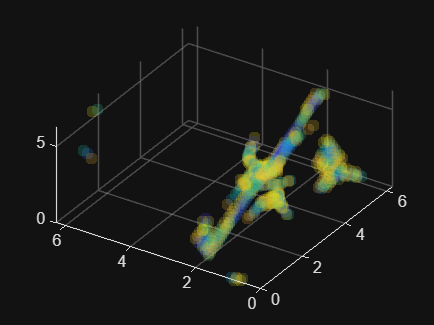

filter_indices1 = angleValue1 < rad2deg(0.1)*0.5;
filtered_angles1 = attGrid(filter_indices1, :);
filtered_positions1 = angleValue1(filter_indices1);

scatter3(filtered_angles1(:,1), filtered_angles1(:,2), filtered_angles1(:,3), 50, filtered_positions1, ...
         'filled','MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 0.2);

xlim([0,2*pi])
ylim([0,2*pi])
zlim([0,2*pi])

colormap;

r2 = [1, 1, -1];
r2 = r2/norm(r2);
b2 = quatrotate(q,r2);
b2 = b2/norm(b2);
expected_sun_sens = real(acosd(dot(b2,r2)))

expected_sun_sens = 22.0088

angleValue2 = zeros(numAnglesChecked,1);

for idx = 1:numAnglesChecked
    q_test = eul2quat(attGrid(idx,:));
    b_test = quatrotate(q_test,r2);
    b_test = b_test/norm(b_test);
    %angleValue2(idx) = acosd(clip(dot(b_test,b2),-1,1));
    angleValue2(idx) = abs(expected_sun_sens - acosd(clip(dot(b_test,r2),-1,1)));
end

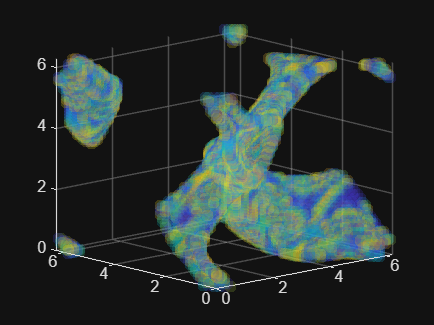

filter_indices2 = angleValue2 < rad2deg(0.1)*0.5;
filtered_angles2 = attGrid(filter_indices2, :);
filtered_positions2 = angleValue2(filter_indices2);

scatter3(filtered_angles2(:,1), filtered_angles2(:,2), filtered_angles2(:,3), 50, filtered_positions2, ...
         'filled','MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 0.2);

xlim([0,2*pi])
ylim([0,2*pi])
zlim([0,2*pi])

colormap;

filter_indices = filter_indices1 & filter_indices2

filter_indices = 250047×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


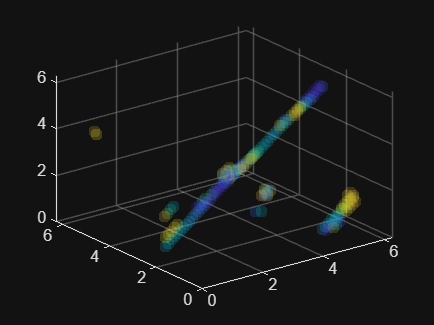

filtered_angles = attGrid(filter_indices, :);
filtered_positions = angleValue2(filter_indices);

scatter3(filtered_angles(:,1), filtered_angles(:,2), filtered_angles(:,3), 50, filtered_positions, ...
         'filled','MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 0.2);

xlim([0,2*pi])
ylim([0,2*pi])
zlim([0,2*pi])

colormap;

angleValue1(filter_indices)

ans =     1.1087
    2.3958
    1.9573
    1.5516
    2.3661
    2.1526
    1.9922
    2.3436
    2.7487
    2.4224


angleValue2(filter_indices)

ans =     0.1059
    1.1073
    2.0729
    0.4387
    1.2309
    1.3005
    0.7560
    1.3502
    0.5948
    1.0539


filtered_angles = attGrid(filter_indices, :)

filtered_angles =     5.2000    1.5000         0
    5.2000    1.6000         0
    5.4000    1.4000    0.1000
    5.3000    1.5000    0.1000
    5.3000    1.6000    0.1000
    5.5000    1.4000    0.2000
    5.4000    1.5000    0.2000
    5.4000    1.6000    0.2000
    5.6000    1.4000    0.3000
    5.5000    1.5000    0.3000


[isMember, rowIndex] = ismember(round(eu_rot,1), attGrid, 'rows')

isMember = logical
   1


rowIndex = 223255


angleValue1(rowIndex) + angleValue2(rowIndex)

ans = 3.0605

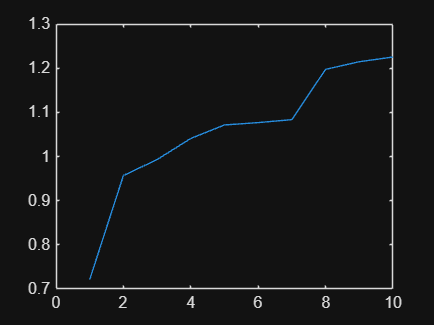

sortAngleValue = angleValue1(filter_indices) + angleValue2(filter_indices);
[sortAngleValue,idx_sort] = sort(sortAngleValue);
sortFiltAngles = filtered_angles(idx_sort, :);

plot(sortAngleValue);
xlim([0 10]);


round(eu_rot,1)

ans =     4.5000    1.5000    5.6000


sortAngleValue(1:8,:)

ans =     0.7214
    0.9569
    0.9931
    1.0409
    1.0714
    1.0767
    1.0835
    1.1974


sortFiltAngles(1:8,:)

ans =     4.9000    1.5000    6.0000
    1.7000    1.6000    2.8000
    1.6000    1.6000    2.7000
    4.8000    1.5000    5.9000
    1.5000    1.6000    2.6000
    1.8000    1.6000    2.9000
    5.0000    1.5000    6.1000
    1.4000    1.6000    2.5000


function av = AngleAcc_(test_rot,r1,r2,b1,expected_sun_sens)
    q_test = eul2quat(test_rot);
    b_test = quatrotate(q_test,r1);
    av1 = real(acosd(dot(b_test,b1)));
    b_test = quatrotate(q_test,r2);
    av2 = abs(expected_sun_sens - real(acosd(dot(b_test,r2))));
    av = av1 + av2;
end

AngleAcc = @(test_rot) AngleAcc_(test_rot,r1,r2,b1,expected_sun_sens);

% Provide an initial guess for the variables
initialGuess = rand(1,3)*2*pi;

% Define bounds for the variables (optional)
lb = [0, 0, 0];  % Lower bounds
ub = [1, 1, 1]*2*pi;  % Upper bounds

% Call fmincon to minimize the function with bounds
options = optimoptions('fmincon','Display','iter');  % Options to display iterations (optional)
[optimalX, minValue] = fmincon(AngleAcc, initialGuess, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    4.597859e+01    0.000e+00    2.944e+01
    1       8    3.578691e+01    0.000e+00    1.700e+02    6.059e+00
    2      12    3.458154e+01    0.000e+00    1.450e+02    2.982e-02
    3      16    2.955803e+01    0.000e+00    1.231e+02    1.399e-01
    4      20    2.967999e+01    0.000e+00    3.321e+01    4.629e-01
    5      24    1.985777e+01    0.000e+00    6.392e+01    8.073e-01
    6      28    1.905416e+01    0.000e+00    6.643e+01    2.478e-02
    7      34    1.954556e+01    0.000e+00    5.090e+01    1.142e-01
    8      38    1.874673e+01    0.000e+00    2.854e+01    3.197e-02
    9      42    1.670674e+01    0.000e+00    1.128e+01    1.278e-01
   10      46    1.672799e+01    0.000e+00    4.386e+00    8.176e-03
   11      50    1.670552e+01    0.000e+00    1.358e+00    3.003e-02
   12      54    1.659928e+01    0.000e+00    4


% Display results
disp(['Optimal X: ', num2str(optimalX)]);

Optimal X: 6.2832     0.70762      6.2832


disp(['Minimum value: ', num2str(minValue)]);

Minimum value: 16.5487
